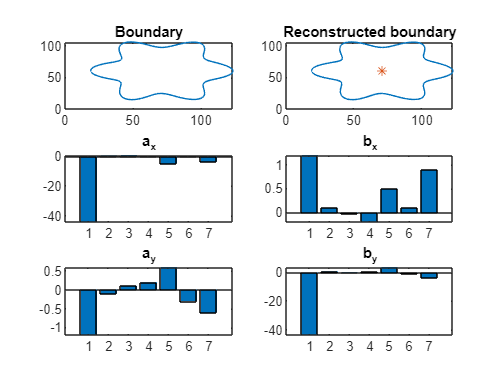

% Ex3
clear variables

ax=[-44.2,0.6,0.7,-0.4,-4.8,-0.01,-3.7];
bx=[1.2, 0.1, -0.03, -0.2, 0.5, 0.1, 0.9];
ay=[-1.2, -0.1, 0.1, 0.2, 0.6, -0.3, -0.6];
by=[-43.8, 0.8, 0.1, 0.4, 3.7, -0.6, -3.6];
ax0=141.6; ay0=121.3;
m=317;
nc=7;
T=m; w=2*pi/T; tau=T/m;
for n=1:m
 X2(n)=ax0/2;
 Y2(n)=ay0/2;
 for k=1:nc
 X2(n)=X2(n)+ax(k)*cos(k*w*n)+bx(k)*sin(k*w*n);
 Y2(n)=Y2(n)+ay(k)*cos(k*w*n)+by(k)*sin(k*w*n);
 end
end
c2=[X2;Y2];
figure, subplot(321), plot(c2(1,:), c2(2,:)); title('Boundary')
subplot(322), plot(c2(1,:),c2(2,:)); hold on; plot(ax0/2,ay0/2,'*');
 title('Reconstructed boundary')
subplot(323), bar(ax), title('a_x'); subplot(324), bar(bx), title('b_x');
subplot(325), bar(ay), title('a_y'); subplot(326), bar(by), title('b_y');